## Ejercicio 1

Inciso a

function [Q, R] = qr1(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando el método de Gram-Schmidt inestable.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxn
    %       R: Matriz triangular superior de tamaño nxn
    %

    [m, n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);

    for j = 1:n
        vj = A(:, j);
        for i = 1:j-1
            R(i, j) = Q(:, i)' * A(:, j);
            vj = vj - R(i, j) * Q(:, i);
        end
        R(j, j) = norm(vj);
        Q(:, j) = vj / R(j, j);
    end
end

Inciso b

function [Q, R] = qr2(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando el método de Gram-Schmidt estable.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxn
    %       R: Matriz triangular superior de tamaño nxn
    %

    [m, n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);
    V = A;

    for i = 1:n
        R(i, i) = norm(V(:, i));
        Q(:, i) = V(:, i) / R(i, i);
        for j = i+1:n
            R(i, j) = Q(:, i)' * V(:, j);
            V(:, j) = V(:, j) - R(i, j) * Q(:, i);
        end
    end
end

Inciso c

function [Q, R] = qr3(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando la triangularización de Householder.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxm
    %       R: Matriz triangular superior de tamaño mxn
    %

    [m, n] = size(A);
    R = A;
    Q = eye(m);

    for j = 1:n
        x = R(j:m, j);
        e1 = zeros(length(x), 1);
        e1(1) = 1;
        vj = sign(x(1)) * norm(x) * e1 + x;
        vj = vj / norm(vj);
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        Q(j:m, :) = Q(j:m, :) - 2 * vj * (vj' * Q(j:m, :));
    end

    Q = Q';
end

Inciso d

m = 20; 
A_random = rand(m);

[Q1, R1] = qr1(A_random);
[Q2, R2] = qr2(A_random);
[Q3, R3] = qr3(A_random);

error = zeros(3,2);

error(1,1) = norm(A_random - Q1 * R1, 2);
error(1,2) = norm(Q1 * Q1' - eye(m), 2);

error(2,1) = norm(A_random - Q2 * R2, 2);
error(2,2) = norm(Q2 * Q2' - eye(m), 2);

error(3,1) = norm(A_random - Q3 * R3, 2);
error(3,2) = norm(Q3 * Q3' - eye(m), 2);

disp(error)

   1.0e-12 *

    0.0007    0.1937
    0.0007    0.0041
    0.0025    0.0013



Inciso e

A_hilbert = hilb(m);

[Q1, R1] = qr1(A_hilbert);
[Q2, R2] = qr2(A_hilbert);
[Q3, R3] = qr3(A_hilbert);
[Q4, R4] = qr(A_hilbert);
error = zeros(4,2);

error(1,1)  = norm(A_hilbert - Q1 * R1, 2);
error(1,2) = norm(Q1 * Q1' - eye(m), 2);

error(1,2) = norm(A_hilbert - Q2 * R2, 2);
error(2,2)  = norm(Q2 * Q2' - eye(m), 2);

error(3,1) = norm(A_hilbert - Q3 * R3, 2);
error(3,2) = norm(Q3 * Q3' - eye(m), 2);

error(4,1) = norm(A_hilbert - Q4 * R4, 2);
error(4,2) = norm(Q4 * Q4' - eye(m), 2);
format long
disp(error)

   0.000000000000000   0.000000000000000
                   0   0.998956338417536
   0.000000000000001   0.000000000000001
   0.000000000000000   0.000000000000001



## Ejercicio 2

Inciso a

m = 12;
x = ones(m, 1); % solución exacta
A = hilb(m);
b = A * x;

fprintf("El número de condición es %d", cond(A))

El número de condición es 16211639047474996

Inciso b

[L, U, P] = lu(A);
y = L \ (P * b);
x_LU = U \ y;

error_LU = norm(x - x_LU, 2)

error_LU =    0.575664393204197


fprintf("El error por LU es %d", error_LU)

El error por LU es 5.756644e-01

Inciso c 

[Q, R] = qr(A);
x_QR = R \ (Q' * b);

error_QR = norm(x - x_QR, 2);
fprintf("El error por QR es %d", error_QR)

El error por QR es 7.049970e-01

Inciso d

L = chol(A, 'lower');
y = L \ b;
x_Chol = L' \ y;

error_Chol = norm(x - x_Chol, 2);
fprintf("El error por Cholesky es %d", error_Chol)

El error por Cholesky es 6.549294e-01

Inciso e

[U, S, V] = svd(A);
x_SVD = V * (S \ (U' * b));


error_SVD = norm(x - x_SVD, 2);
fprintf("El error por SVD es %d", error_SVD)

El error por SVD es 2.004997e+00

Inciso g

rango = 9;
A_nu_inv = V(:, 1:rango) * inv(S(1:rango, 1:rango)) * U(:, 1:rango)';
x_aprox = A_nu_inv * b;

error_approx = norm(x - x_aprox, 2);
fprintf("El error por rango 9 es %d", error_approx)

El error por rango 9 es 6.981971e-06

## Ejercicio 3

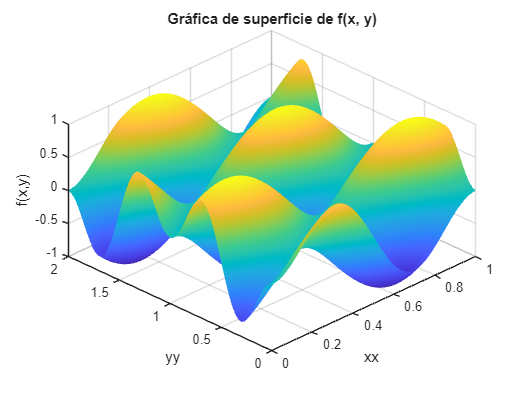

x = linspace(0,1,100);
y = linspace(0,2,200);

[xx,yy] = meshgrid(x,y);

f = @(x,y) sin(2.*pi.*(x+y)).*sin(pi.*(x-y));

figure;
surf(xx,yy,f(xx,yy))
view([-45 45])
shading interp
xlabel('xx')
ylabel('yy')
zlabel('f(x,y)')
title('Gráfica de superficie de f(x, y)')

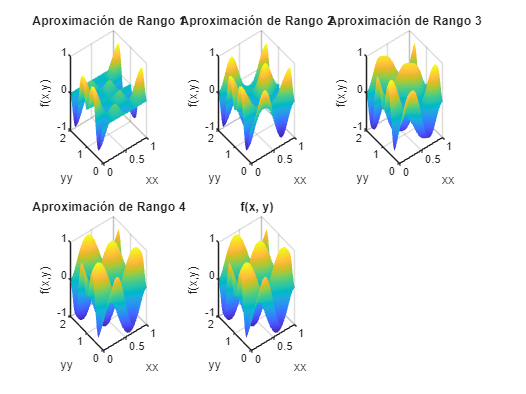


zz = f(xx,yy);
[U,S,V] = svd(zz);
val = diag(S);
aprox = cell(4,1);
aprox{1} = val(1)*U(:,1)*V(:,1)';
for i = 2:4
    aprox{i} = aprox{i-1} + val(i)*U(:,i)*V(:,i)';
end

figure;
for i = 1:4
    subplot(2,3,i);
    surf(xx, yy, aprox{i})
    shading interp
    xlabel('xx')
    ylabel('yy')
    zlabel('f(x,y)')
    title(sprintf('Aproximación de Rango %d', i))
end

subplot(2,3,5)
surf(xx,yy,f(xx,yy))
shading interp
xlabel('xx')
ylabel('yy')
zlabel('f(x,y)')
title('f(x, y)')

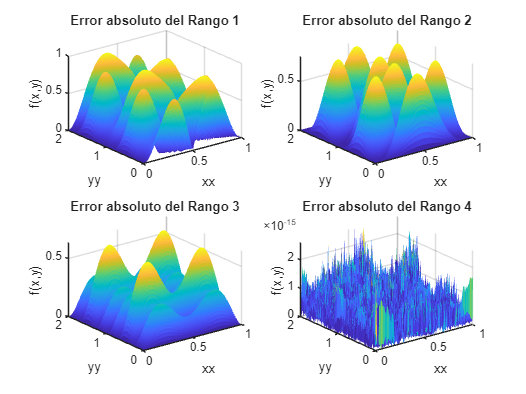


figure;
error = cell(4,1);
for i = 1:4
    error{i} = abs(f(xx, yy) - aprox{i});
    subplot(2, 2, i)
    surf(xx, yy, error{i})
    shading flat
    xlabel('xx')
    ylabel('yy')
    zlabel('f(x,y)')
    title(sprintf('Error absoluto del Rango %d', i))
end


disp(val(1:4))

  35.791933448753497
  35.440972052131968
  35.090062695868767
  35.090062695868752



rank(zz)

ans =      4


   
disp(norm(cos(2.*pi.*x).*cos(pi.*x)) * norm(sin(2.*pi.*y).*sin(pi.*y)))

  35.791933448753504



disp(norm(sin(2.*pi.*x).*sin(pi.*x)) * norm(cos(2.*pi.*y).*cos(pi.*y)))

  35.440972052131976



disp(norm(sin(2.*pi.*x).*cos(pi.*x)) * norm(cos(2.*pi.*y).*sin(pi.*y)))

  35.090062695868752



disp(norm(cos(2.*pi.*x).*sin(pi.*x)) * norm(sin(2.*pi.*y).*cos(pi.*y)))

  35.090062695868752



## Ejercicio 4

## Ejercicio 7

## Ejercicio 8